# Sampling a 4-dimensional MultiVariate Normal distribution (MVN) via the ParaMonte library's ParaDRAM routine

**NOTE**

If you are viewing an HTML version of this MATLAB live script on the web, you can download the corresponding MATLAB live script ***.mlx** file to this HTML page at,

[https://github.com/cdslaborg/paramontex/blob/master/MATLAB/mlx/sampling_multivariate_normal_density_function_via_paradram.mlx?raw=true](https://github.com/cdslaborg/paramontex/blob/master/MATLAB/mlx/sampling_multivariate_normal_density_function_via_paradram.mlx?raw=true)

This code, along with other MATLAB live scripts, is located at,

[https://github.com/cdslaborg/paramontex/tree/master/MATLAB/mlx](https://github.com/cdslaborg/paramontex/tree/master/MATLAB/mlx)

Once you download the file, open it in MATLAB to view and interact with its contents, which is the same as what you see on this page.

**NOTE**

 This ParaDRAM sampler example is **also available in Python language** as a Jupyter Notebook, on this page,  

[https://nbviewer.jupyter.org/github/cdslaborg/paramontex/blob/master/Python/Jupyter/sampling_multivariate_normal_density_function_via_paradram.ipynb](https://nbviewer.jupyter.org/github/cdslaborg/paramontex/blob/master/Python/Jupyter/sampling_multivariate_normal_density_function_via_paradram.ipynb)

This Jupyter Notebook, along with other Python Jupyter Notebooks, is located at,

[https://github.com/cdslaborg/paramontex/tree/master/Python/Jupyter](https://github.com/cdslaborg/paramontex/tree/master/Python/Jupyter)

## **The logic of Monte Carlo sampling** is very simple

**==========================================================**

You have a mathematical objective function defined on a **ndim**-dimensional domain. Typically, this domain is defined on the space of real numbers. In general, understanding and visualizing the structure of such objective functions is an extremely difficult task, if not impossible. As a better alternative, you employ Monte Carlo techniques that can randomly explore the structure of the objective function and find the function's extrema. 

In the following example below, an example of one of the simplest such objective functions, the **Multivariate Normal Distribution (MVN)**, is constructed and sampled using the ParaMonte library samplers, here, the **ParaDRAM** sampler (**Delayed-Rejection Adaptive Metropolis-Hastings Markov Chain Monte Carlo sampler**).  

First, we will clean up the MATLAB environment and make sure the path to the ParaMonte library is in MATLAB's path list.

clc;
clear all;
close all;
format compact; format long;

%%%%%%%%%%%% IMPORTANT %%%%%%%%%%%%%
% Set the path to the ParaMonte library:
% Change the following path to the ParaMonte library root directory, 
% otherwise, make sure the path to the ParaMonte library is already added
% to MATLAB's path list.

pmlibRootDir = './';
addpath(genpath(pmlibRootDir),"-begin");
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% change MATLAB's working directory to the folder containing this script
% if MATLAB Live Scripts did not create a temporary folder, we would not
% have all of these problems!

try
    setwd; % You can download this file from the same location where you downloaded this MATLAB live script on GitHub.
catch % alas, we will have to run the simulations in MATLAB Live Script's temporary folder
    filePath = mfilename('fullpath');
    [currentDir,fileName,fileExt] = fileparts(filePath); cd(currentDir);
    cd(fileparts(mfilename('fullpath'))); % Change working directory to source code directory.
end

Now, suppose we want to sample random points from a [multivariate Normal Probability Density Function (PDF)](https://en.wikipedia.org/wiki/Multivariate_normal_distribution). The following MATLAB function **getLogFunc()** returns the **natural logarithm** of the Probability Density Function of the multivariate Normal PDF. For the moment, let's name this function **getLogFunc_bad()**. The reason for this naming will become clear soon.  

NDIM = 4; % the number of dimensions of the domain of the objective function
getLogFunc_bad = @(point) log( mvnpdf( point ... The point at which the PDF of the multivariate normal distribution is computed. THIS IS A COLUMN VECTOR.
                                     , [-10.; 15.; 20.; 0.0]   ... This is the mean of the multivariate normal distribution. THIS IS A COLUMN VECTOR.
                                     , [ 1.0, .45, -.3, 0.0 ...
                                       ; .45, 1.0, 0.3, -.2 ...
                                       ; -.3, 0.3, 1.0, 0.6 ...
                                       ; 0.0, -.2, 0.6, 1.0 ...
                                       ] ... This is the covariance of the multivariate normal distribution. 
                                     ) ...
                             ); % Note that the return value of getLogFunc must be always in natural logarithm.

**IMPORTANT**

Since the mathematical objective functions (e.g., probability density functions) can take extremely small or large values, we often work with their **natural logarithms** of the objective functions instead of the objective function itself. This is **the reason behind the naming convention used in the ParaMonte library** for the user's objective functions: **getLogFunc**, indicating that the **user must provide a function that returns the natural logarithm of the target objective function**.  

**IMPORTANT**

Note that in MATLAB all vectors and arrays are, by default, **column-major**, and so is the input value, **point**, to **getLogFunc**. This means that the size of **point** is **(ndim,1)**. Thus, **all other vectors **that interact with **point**, for example, the **mean **vector, **must be **also of **the same size as point**: **(ndim,1)**.

**DIGRESSION**

Notice in the above that we suffixed the objective function with `_bad`. This is for a few **important** reasons:

- This function's evaluation involves a `log(exp())` term in its definition. If the origin of the `exp()` term is not clear to you, take a look at the definition of the MVN  distribution in the link provided above.  This is computational very  expensive and in general, is considered a bad implementation.

- The evaluation of the function as implemented in the above requires an inverse-covariance matrix on each call made to `getLogFunc_bad()`. This is completely redundant as the value of the covariance matrix does not change throughout the simulation. Consequently, a lot of  computational resources are wasted for nothing.

- This implementation of the MVN distribution is quite prone to numerical **overflow** and **underflow**, which could cause the simulations to crash at runtime. For example, when the input value for `point` happens to be too far from the `mean` of the MVN distribution, it is likely that the resulting probability  density function value for the MVN would be so small that the computer rounds it to zero. Then `log(0.0)` in `getLogFunc_bad()` becomes undefined and the simulation crashes, in the best-case scenario and will notice the problem.

It is, therefore, important to implement a numerically efficient,  fault-tolerant MVN PDF calculator that resolves all of the above  concerns. This is possible if we take a second look at the equation for  the MVN PDF and try directly implement as our objective function,

% the number of dimensions of the domain of the objective function: MVN

NDIM = 4;

% This is the mean of the MVN distribution.

MEAN =  [-10; 15.; 20.; 0.0];

% This is the covariance matrix of the MVN distribution.

COVMAT = [ 1.0,.45,-.3,0.0 ... 
         ; .45,1.0,0.3,-.2 ...
         ; -.3,0.3,1.0,0.6 ...
         ; 0.0,-.2,0.6,1.0 ...
         ];

% This is the inverse of the covariance matrix of the MVN distribution.

INVCOV = inv(COVMAT);

% This is the log of the coefficient used in the definition of the MVN.

MVN_COEF = NDIM * log( 1. / sqrt(2.*pi) ) + log( sqrt(det(INVCOV)) );

% the logarithm of objective function: log(MVN)

getLogFuncStandard = @(normedPoint) MVN_COEF - 0.5 * ( dot(normedPoint', INVCOV * normedPoint) );

getLogFunc = @(point) getLogFuncStandard(MEAN-point);

Now, let's compare the performance of the two implementations above,

tic
for i = 1:1000
getLogFunc_bad( [0.0; 0.0; 0.0; 0.0] );
end
toc

Elapsed time is 0.077233 seconds.


tic
for i = 1:1000
getLogFunc( [0.0; 0.0; 0.0; 0.0] );
end
toc

Elapsed time is 0.031603 seconds.


The good implementation is or can be **more than three or four times more efficient** than the naive implementation of the objective function!

Now, let's compare the fault-tolerance of the two implementations by assigning large values to the elements of the input `point` array,

getLogFunc(10000*ones(NDIM,1))

ans =     -1.449064065712371e+08

getLogFunc_bad(10000*ones(NDIM,1))

ans =   -Inf

Now, this may sound to you like being too meticulous, but, **a good fault-tolerant implementation of the objective function is absolutely essential in Monte Carlo simulations**, and this example objective function here is no exception. The `-inf` value that `getLogFunc_bad()` yields, will certainly lead to a severe catastrophic crash of a Monte  Carlo simulation (You can try it below at your own risk!).

## Building a ParaDRAM simulation on a single processor

**=================================================================**

We will sample random points from this objective function by calling the **ParaDRAM** sampler (**Para**llel **D**elayed-**R**ejection **A**daptive **M**etropolis-Hastings Markov Chain Monte Carlo sampler) of the ParaMonte library.  

**Note:** To run the ParaMonte samplers **in parallel**, visit the [ParaMonte library's documentation website](http://cdslab.org/paramonte/notes/run/matlab/).

We will first create an instance of the **paramonte** class,

pm = paramonte();


:::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::
::::                                                                                       ::::

       _/_/_/_/                                   _/_/    _/_/
        _/    _/                                  _/_/_/_/_/                     _/
       _/    _/ _/_/_/_/   _/ /_/_/ _/_/_/_/     _/  _/  _/   _/_/   _/_/_/   _/_/_/  _/_/_/
      _/_/_/   _/    _/   _/_/     _/    _/     _/      _/  _/   _/ _/    _/   _/   _/_/_/_/                        
     _/       _/    _/   _/       _/    _/     _/      _/  _/   _/ _/    _/   _/   _/    
  _/_/_/       _/_/_/_/ _/         _/_/_/_/ _/_/_/  _/_/_/  _/_/  _/    _/   _/_/   _/_/_/


                                          ParaMonte
                                   plain powerful parallel
                                     Monte Carlo library
                                        Version 1.1.0

::::                                       

**DIGRESSION**

We can **get** the ParaMonte library interface version,

pm.version.interface.get()

ans = "ParaMonte MATLAB Interface Version 1.1.0"

pm.version.interface.dump()

ans = "1.1.0"

pm.version.kernel.get()

ans = "ParaMonte MATLAB Kernel Version 1.1.0"

pm.version.kernel.dump()

ans = "1.1.0"

We can also verify the existence of the essential components of the  current installation of the ParaMonte Python library on the system,

pm.verify();


:::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::::
::::                                                                                       ::::

       _/_/_/_/                                   _/_/    _/_/
        _/    _/                                  _/_/_/_/_/                     _/
       _/    _/ _/_/_/_/   _/ /_/_/ _/_/_/_/     _/  _/  _/   _/_/   _/_/_/   _/_/_/  _/_/_/
      _/_/_/   _/    _/   _/_/     _/    _/     _/      _/  _/   _/ _/    _/   _/   _/_/_/_/                        
     _/       _/    _/   _/       _/    _/     _/      _/  _/   _/ _/    _/   _/   _/    
  _/_/_/       _/_/_/_/ _/         _/_/_/_/ _/_/_/  _/_/_/  _/_/  _/    _/   _/_/   _/_/_/


                                          ParaMonte
                                   plain powerful parallel
                                     Monte Carlo library
                                        Version 1.1.0

::::                                       

You can also check the current version of paramonte that you have on your system,

### Setting up the ParaDRAM simulation specifications

**====================================================**

Now, we create an instance of the ParaDRAM sampler class,  

pmpd = pm.ParaDRAM();

The **simplest scenario** is to **run the simulation with the default specifications** that are appropriately determined by the ParaDRAM sampler. However, for the purpose of clarity reproducibility, we will specify a few  simulation specs,

For a complete list of all ParaDRAM simulation specifications, visit the [ParaDRAM simulation specifications webpage](https://www.cdslab.org/paramonte/notes/usage/paradram/specifications/).

#### **The simulation output file names and storage path**

We will store all output files in a directory with the same name as this Jupyter Notebook's name and with the same prefix.

By default, all ParaDRAM simulation output files are named properly (see [this page](https://www.cdslab.org/paramonte/notes/usage/paradram/output/) for a review of ParaDRAM simulation output files). **In general, it is a good habit to specify an output file prefix for any ParaDRAM simulation**. This way, the restart of an incomplete simulation, if it happens for some reason, would be seamless and doable by just rerunning the simulation, without any change of any sort to any parts of the codes or the simulation.

We will prefix all simulation output files the same as the filename of this script,

pmpd.spec.outputFileName = "./sampling_multivariate_normal_density_function_via_paradram/mvn_serial";

The above **outputFileName** will result in the generation of a folder named **sampling_multivariate_normal_density_function_via_paradram**, which will keep the simulation output files, all of which are prefixed with **mvn_serial**.

**Note**: If the specified prefix ends with a **forward slash /** on Linux/macOS or with a **backslash \ **on Windows, then the prefix provided will serve as the directory in which the output files will be stored.

#### **Ensuring the reproducibility of the results**

We will also initialize the random seed to a fixed number to ensure the reproducibility of the simulation results in the future,

pmpd.spec.randomSeed = 3751;

#### Setting the output sample size to a non-default value

Not so important, but we will also specify a **chainSize** here, 30000, the number of **unique points** to be sampled from the objective function. This number is much smaller than the default 100,000 unique sample points of the sampler.

pmpd.spec.chainSize = 30000;

#### **The default domain of the objective function**

The default starting point of the sampler for exploring the objective function is the center of the domain of the objective function. The default domain of the objective function chosen by the sampler is $[-\infty , +\infty]$ along each dimension of the objective function. **This is a fine default assumption for this particular simulation and in most other scenarios**. If needed, you can change them via the following attributes,

pmpd.spec.domainLowerLimitVec = -1.e300 * ones(NDIM,1); % set the lower limits of the domain of the objective function to negative infinity (This is the default value)
pmpd.spec.domainUpperLimitVec = +1.e300 * ones(NDIM,1); % set the upper limits of the domain of the objective function to negative infinity (This is the default value)

The ParaDRAM sampler guarantees to not sample any points outside the hypercube defined by the above limits.

### **Calling the ParaDRAM sampler**

**===============================**

Note that none of the above specification settings were necessary, but is in general a good habit to define them prior to the simulation.

We now call the ParaDRAM sampler routine to run the sampling simulation. The ParaDRAM sampler method takes only two arguments. We can call it like the following,

pmpd.runSampler ( NDIM ... This is the number of dimensions of the objective function
                , getLogFunc ... This is the objective function
                );

ParaDRAM - NOTE: Running the ParaDRAM sampler in serial mode...
ParaDRAM - NOTE: To run the ParaDRAM sampler in parallel mode visit: cdslab.org/pm


************************************************************************************************************************************
************************************************************************************************************************************
****                                                                                                                            ****
****                                                                                                                            ****
****                                                         ParaMonte                                                          ****
****                                                  Plain Powerful Parallel                                                   ****
****                                                 

This will print the realtime simulation progress information on your **MATLAB prompt window** (if you are on a Windows system) and on the **Bash terminal** from which you invoked the **matlab** command to open MATLAB. Once the simulation is finished, the ParaDRAM routine generates 5 output files, each of which contains information about certain aspects of the simulation,

- [**mvn_serial_process_1_report.txt**](https://raw.githubusercontent.com/cdslaborg/paramontex/master/MATLAB/mlx/sampling_multivariate_normal_density_function_via_paradram/mvn_serial_process_1_report.txt)**:** This file contains reports about all aspects of the simulation, from the very beginning of the simulation to the very last step, including the  postprocessing of the results and final sample refinement.

- [**mvn_serial_process_1_progress.txt**](https://raw.githubusercontent.com/cdslaborg/paramontex/master/MATLAB/mlx/sampling_multivariate_normal_density_function_via_paradram/mvn_serial_process_1_progress.txt)**:** This file contains dynamic realtime information about the simulation  progress. The frequency of the progress report to this file depends on  the value of the simulation specification `progressReportPeriod`.

- [**mvn_serial_process_1_sample.txt**](https://raw.githubusercontent.com/cdslaborg/paramontex/master/MATLAB/mlx/sampling_multivariate_normal_density_function_via_paradram/mvn_serial_process_1_sample.txt)**: **This file contains the final fully-refined decorrelated i.i.d. random sample from the objective function.

- [**mvn_serial_process_1_chain.txt**](https://raw.githubusercontent.com/cdslaborg/paramontex/master/MATLAB/mlx/sampling_multivariate_normal_density_function_via_paradram/mvn_serial_process_1_chain.txt)**:** This file contains the Markov chain, generally in either binary or  condensed (compact) ASCII format to improve the storage efficiency of  the chain on your computer.

outPath = fullfile(currentDir,"sampling_multivariate_normal_density_function_via_paradram");
outFileList = ["mvn_serial_process_1_report.txt", "mvn_serial_process_1_progress.txt", "mvn_serial_process_1_sample.txt", "mvn_serial_process_1_chain.txt"];
for file = outFileList(end:-1:1)
    open(fullfile(outPath,file))
end

Upon finishing the simulation, the sampler provides hints on how to postprocess the results. Now, we can read the generated output sample, contained in the file suffixed with `*_sample.txt`. 

pmpd.readSample()

ParaDRAM - WARNING: The ParaDRAM input simulation specification pmpd.spec.outputDelimiter is not set.
ParaDRAM - WARNING: This information is essential for successful reading of the requested sample file(s).
ParaDRAM - WARNING: Proceeding with the default assumption of comma-delimited sample file contents...

ParaDRAM - NOTE: 1 files detected matching the pattern: "./sampling_multivariate_normal_density_function_via_paradram/mvn_serial*"


ParaDRAM - NOTE: processing file: D:\Dropbox\Projects\20180101_ParaMonte\paramontex\MATLAB\mlx\sampling_multivariate_normal_density_function_via_paradram\mvn_serial_process_1_sample.txt
ParaDRAM - NOTE: reading file contents... 
ParaDRAM - NOTE: done in 0.702300 seconds.
ParaDRAM - NOTE: computing the sample correlation matrix...
ParaDRAM - NOTE: creating the heatmap plot object from scratch...
ParaDRAM - NOTE: done in 0.555410 seconds.
ParaDRAM - NOTE: computing the sample covariance matrix...
ParaDRAM - NOTE: creating the heatmap plot object from s

By default, the ParaDRAM sampler generated a highly refined decorrelated final sample, essentially refining the Markov chain for as long as there is any residual auto-correlation in any of the individual variables of the Markov chain that has been sampled. This is an extremely strong and conservative refinement strategy (and it is so for a good reason: to **ensure independent and identically distributed (i.i.d.) samples from the objective function**). However, this extreme refinement can be mitigated and controlled by the setting the following ParaDRAM simulation specification variable prior to the simulation run,

pmpd.spec.sampleRefinementCount = 1;

Rerun the simulation with this specification set and, you will notice a **three-fold** increase in the final sample size, from `7244` to `22140`. Note that the above specification has to be set **before** running the simulation above if you really want to use it. A value of `1` will cause the ParaDRAM sampler for only one round, which what most people in the MCMC community do.

To quickly visualize the generated sample as a histogram, try,

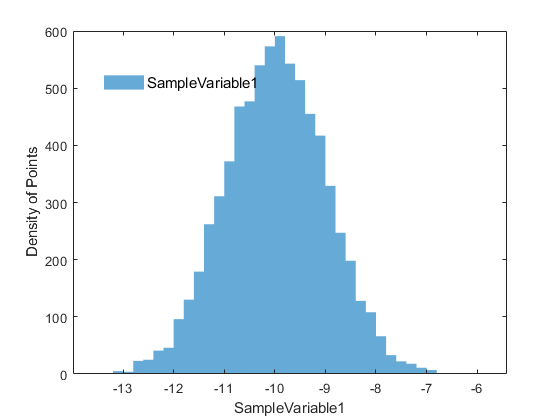

pmpd.sampleList{1}.plot.histogram.plot()

To plot all of the sampled variables, try,

pmpd.sampleList{1}.df.Properties.VariableNames

ans = 1×5 cell array
    {'SampleLogFunc'}    {'SampleVariable1'}    {'SampleVariable2'}    {'SampleVariable3'}    {'SampleVariable4'}

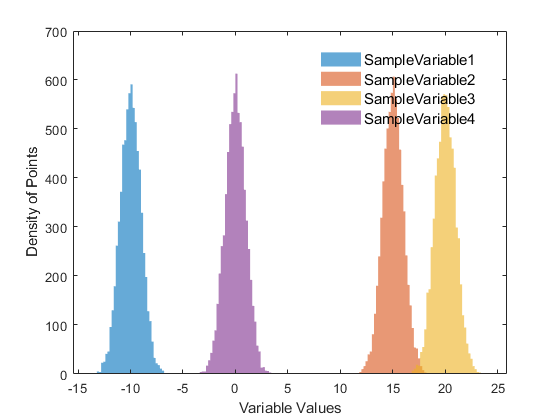

pmpd.sampleList{1}.plot.histogram.xcolumns = pmpd.sampleList{1}.df.Properties.VariableNames(2:end);
pmpd.sampleList{1}.plot.histogram.plot();

You can reset the histogram plot settings by the following,

pmpd.sampleList{1}.plot.reset("histogram")

ParaDRAM - NOTE: resetting the properties of the histogram plot...


You can also rebuild the histogram object from scratch, which includes reading again the input data used in the plotting from the dataFrame, by specifying the input parameter **"hard"**,

pmpd.sampleList{1}.plot.reset("histogram","hard")

ParaDRAM - NOTE: creating the histogram plot object from scratch...


`Make a trace plot of the refined sample,`

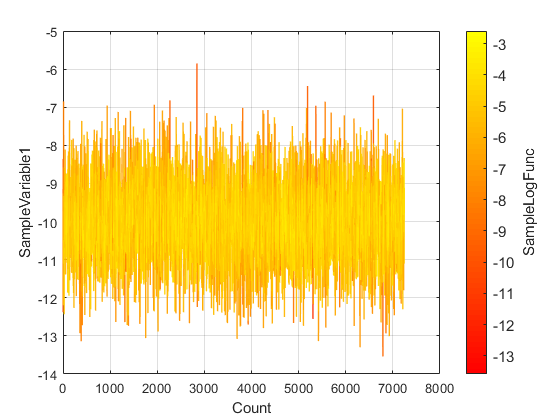

pmpd.sampleList{1}.plot.line.plot()

`We can simply take the axis logarithmic scale, `

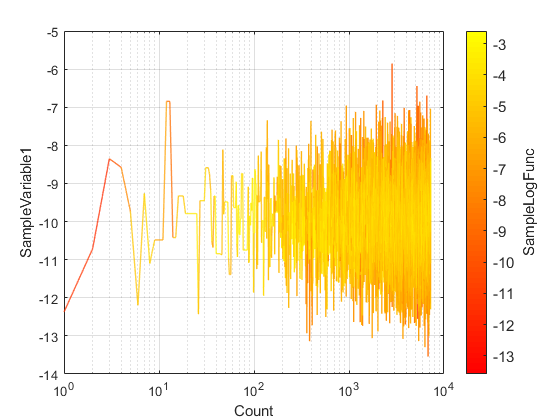

pmpd.sampleList{1}.plot.line.plot();
set(gca,'xscale','log','yscale','linear');

We can also include more variables in a single trace plot, for example, the the first, second, and the fourth dimensions of the objective function,

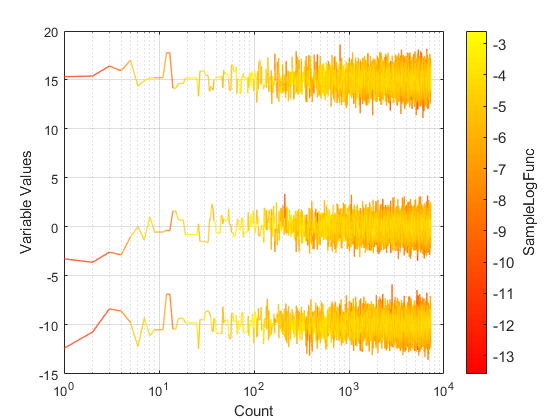

pmpd.sampleList{1}.plot.line.plot("ycolumns",[2,3,5]); % these are the column numbers in the dataFrame pmpd.sampleList{1}.df
set(gca,'xscale','log','yscale','linear');

By default, the color of the line in the trace-plot will represent the value returned by `getLogFunc()` at the given sampled point. 

pmpd.sampleList{1}.plot.line.ccolumns

ans = "SampleLogFunc"

To turn the color off, you can instead try,

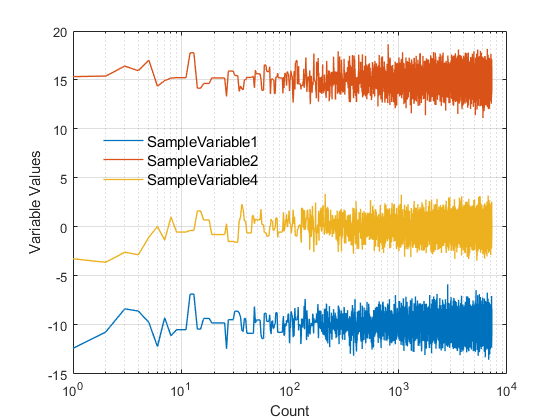

pmpd.sampleList{1}.plot.line.surface_kws.enabled = false; % disable varying-color lines
pmpd.sampleList{1}.plot.line.plot_kws.enabled = true; % enable regular plot lines
pmpd.sampleList{1}.plot.line.plot("ycolumns",[2,3,5]); % these are the column numbers in the dataFrame pmpd.sampleList{1}.df
set(gca,'xscale','log','yscale','linear');

We can also change the properties of the lines as we wish,

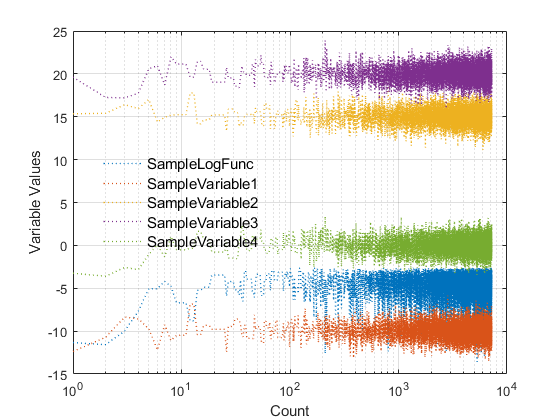

pmpd.sampleList{1}.plot.line.plot_kws.linewidth = 1.0;
pmpd.sampleList{1}.plot.line.plot_kws.linestyle = ":"; % you can add any new proprty to plot_kws, that is an input argument to MATLAB's plot().
pmpd.sampleList{1}.plot.line.plot("ycolumns",["SampleLogFunc",2:5]); % You can mix column names with column numbers
set(gca,'xscale','log','yscale','linear');

To make a **scatter trace-plot** of the sampled points, try,

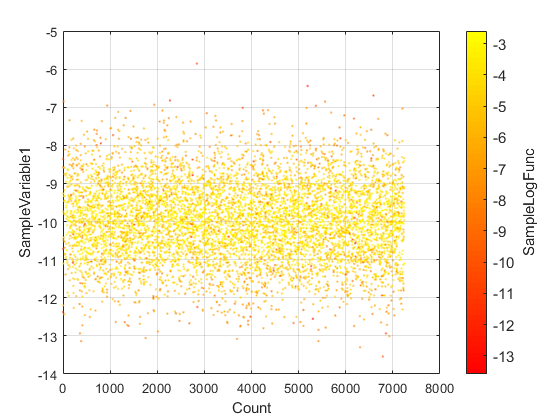

pmpd.sampleList{1}.plot.scatter.plot();

How about plotting other variables?

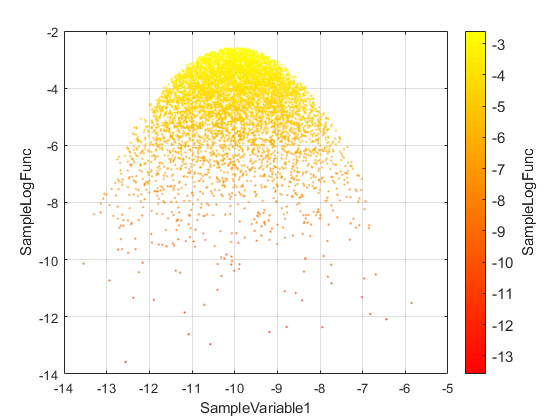

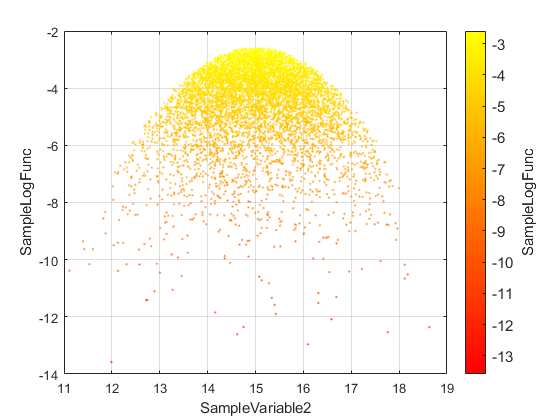

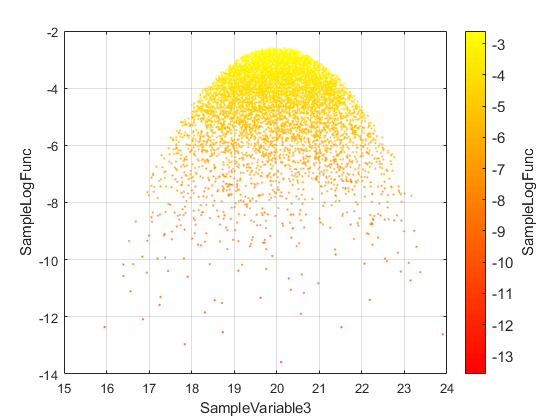

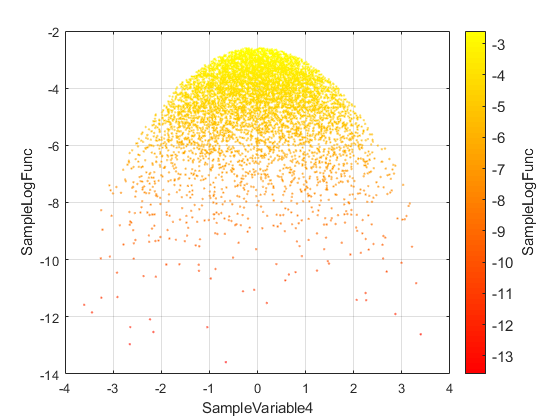

for variableName = pmpd.sampleList{1}.df.Properties.VariableNames(2:end)
    pmpd.sampleList{1}.plot.scatter.plot("xcolumns",variableName,"ycolumns","SampleLogFunc");
end

Let's turn off the scatter plot's varying colors and give it single color,

pmpd.sampleList{1}.plot.reset("scatter","hard")

ParaDRAM - NOTE: creating the scatter plot object from scratch...


pmpd.sampleList{1}.plot.scatter.scatter_kws

ans = struct with fields:
           marker: "."
    singleOptions: {}
             size: 10
          enabled: 1

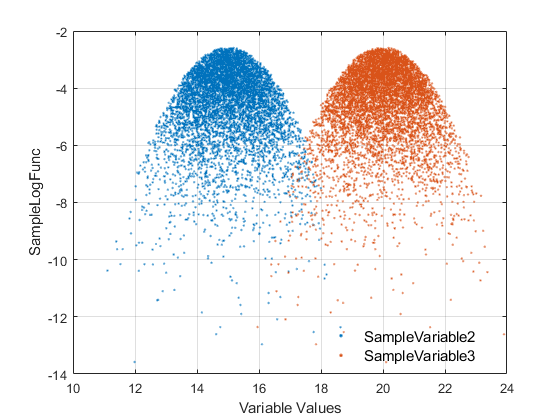

pmpd.sampleList{1}.plot.scatter.scatter_kws.cdata = []; % set the marker color to the default MATLAB colors
pmpd.sampleList{1}.plot.scatter.plot("xcolumns",[3,4],"ycolumns","SampleLogFunc");

How about lineScatter plots?

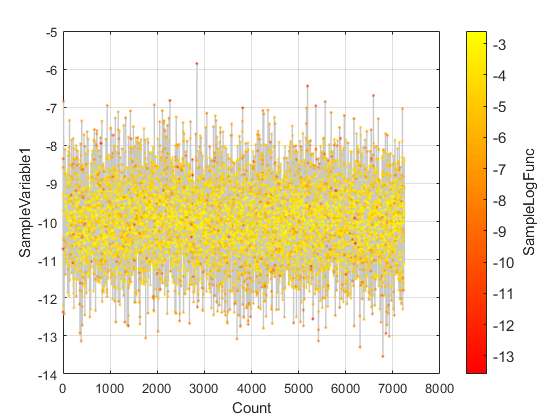

pmpd.sampleList{1}.plot.lineScatter.plot();

plot it on logarithmic axis,

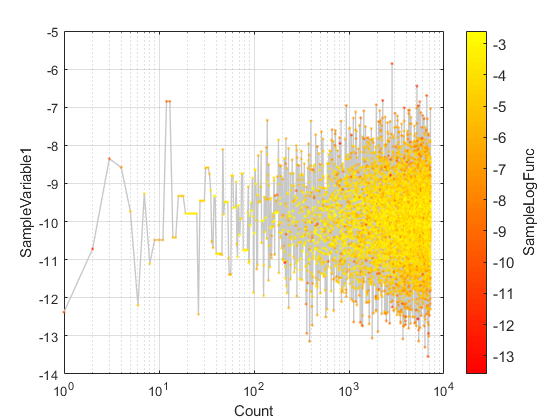

pmpd.sampleList{1}.plot.lineScatter.plot(); 
set(gca,'xscale','log','yscale','linear');

Let's turn off the varying-color,

pmpd.sampleList{1}.plot.reset("lineScatter")

ParaDRAM - NOTE: resetting the properties of the lineScatter plot...


pmpd.sampleList{1}.plot.lineScatter.ccolumns

ans = "SampleLogFunc"

pmpd.sampleList{1}.plot.lineScatter.colormap

ans = "autumn"

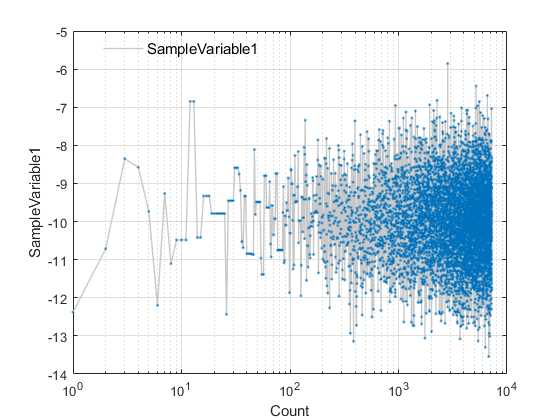

pmpd.sampleList{1}.plot.lineScatter.scatter_kws.cdata = []; % this resets the color of the scatter plot to the default MATLAB colors.
%pmpd.sampleList{1}.plot.lineScatter.scatter_kws.enabled
%pmpd.sampleList{1}.plot.lineScatter.scatter_kws.c = "red";
pmpd.sampleList{1}.plot.lineScatter.plot();
set(gca,'xscale','log','yscale','linear');

Make 3D line plots instead of 2D line plots,

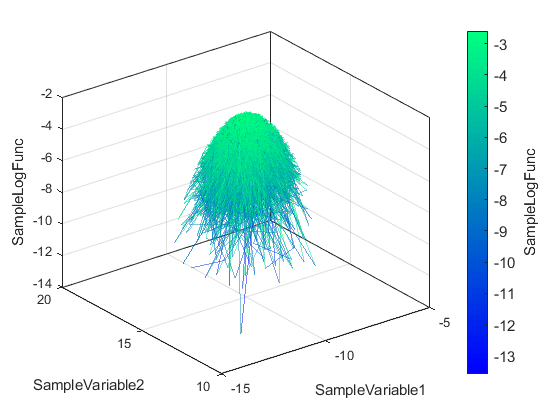

pmpd.sampleList{1}.plot.line3.plot();

Let's change the variables to plot,

disp(pmpd.sampleList{1}.plot.line3.xcolumns);

    'SampleVariable1'


pmpd.sampleList{1}.plot.line3.xcolumns = {}; % reset the x-axis variable to the MCMC counts
pmpd.sampleList{1}.plot.line3.ycolumns = "SampleVariable1"; % ,"SampleVariable2"; % reset the y-axis variable to the first variable. We could include more variables.
pmpd.sampleList{1}.plot.line3.zcolumns % we will keep the z-axis as is: SampleLogFunc

ans = "SampleLogFunc"

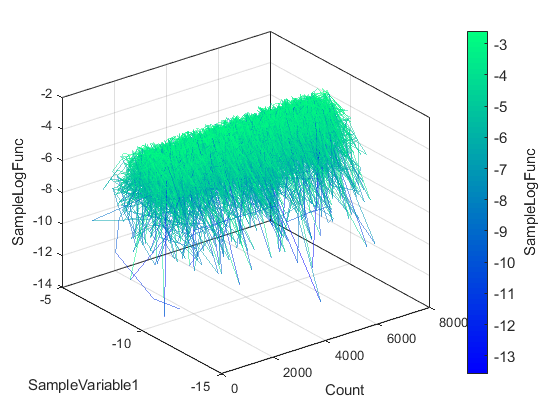

pmpd.sampleList{1}.plot.line3.plot();

Let's make a bivariate grid plot of the sample,

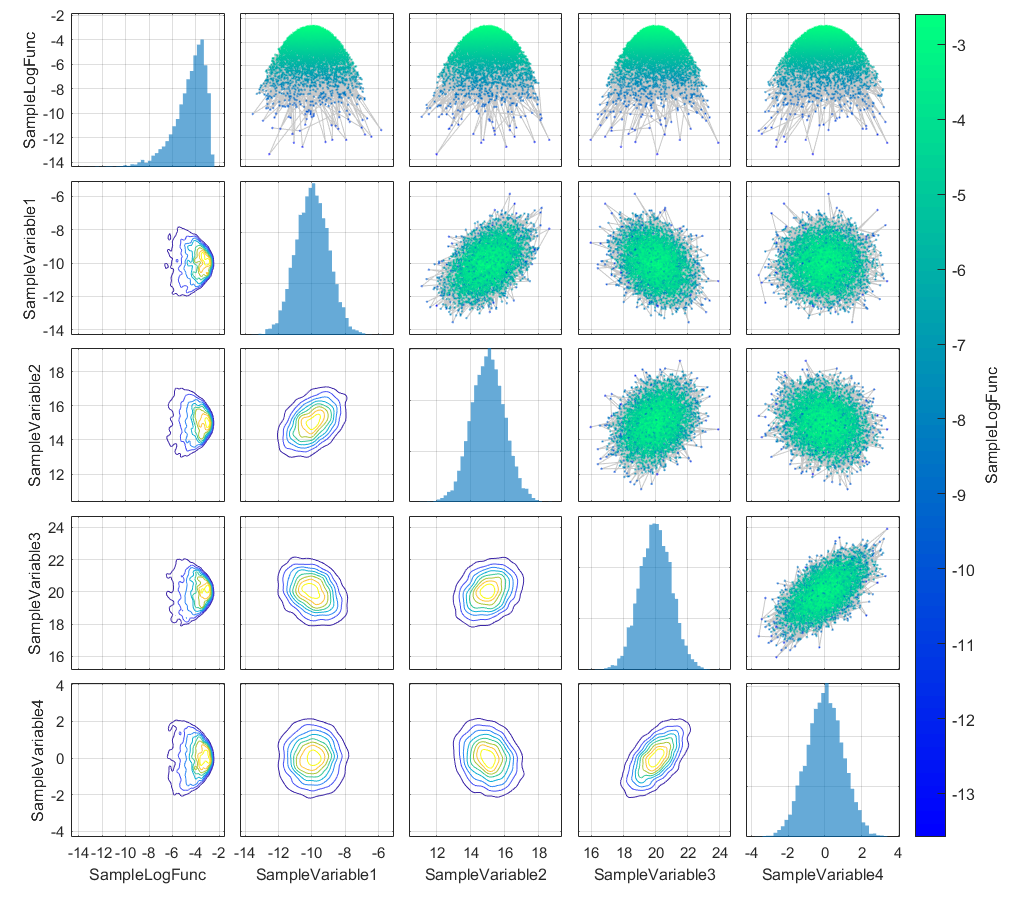

generating subplot #1: (1,1) out of 25
generating subplot #2: (1,2) out of 25
generating subplot #3: (1,3) out of 25
generating subplot #4: (1,4) out of 25
generating subplot #5: (1,5) out of 25
generating subplot #6: (2,1) out of 25
generating subplot #7: (2,2) out of 25
generating subplot #8: (2,3) out of 25
generating subplot #9: (2,4) out of 25
generating subplot #10: (2,5) out of 25
generating subplot #11: (3,1) out of 25
generating subplot #12: (3,2) out of 25
generating subplot #13: (3,3) out of 25
generating subplot #14: (3,4) out of 25
generating subplot #15: (3,5) out of 25
generating subplot #16: (4,1) out of 25
generating subplot #17: (4,2) out of 25
generating subplot #18: (4,3) out of 25
generating subplot #19: (4,4) out of 25
generating subplot #20: (4,5) out of 25
generating subplot #21: (5,1) out of 25
generating subplot #22: (5,2) out of 25
generating subplot #23: (5,3) out of 25
generating subplot #24: (5,4) out of 25
generating subplot #25: (5,5) out of 25


pmpd.sampleList{1}.plot.grid.plot();

In the above plot, **the lower-triangle contour subplots represent the contours of the density of sampled points**.

Let's change the diagonal plots of the grid plot to **histfit**,

pmpd.sampleList{1}.plot.reset("grid") % reset the grid plot to the original settings

ParaDRAM - NOTE: resetting the properties of the grid plot...


pmpd.sampleList{1}.plot.grid.layout.plotType.diag

ans = "histogram"

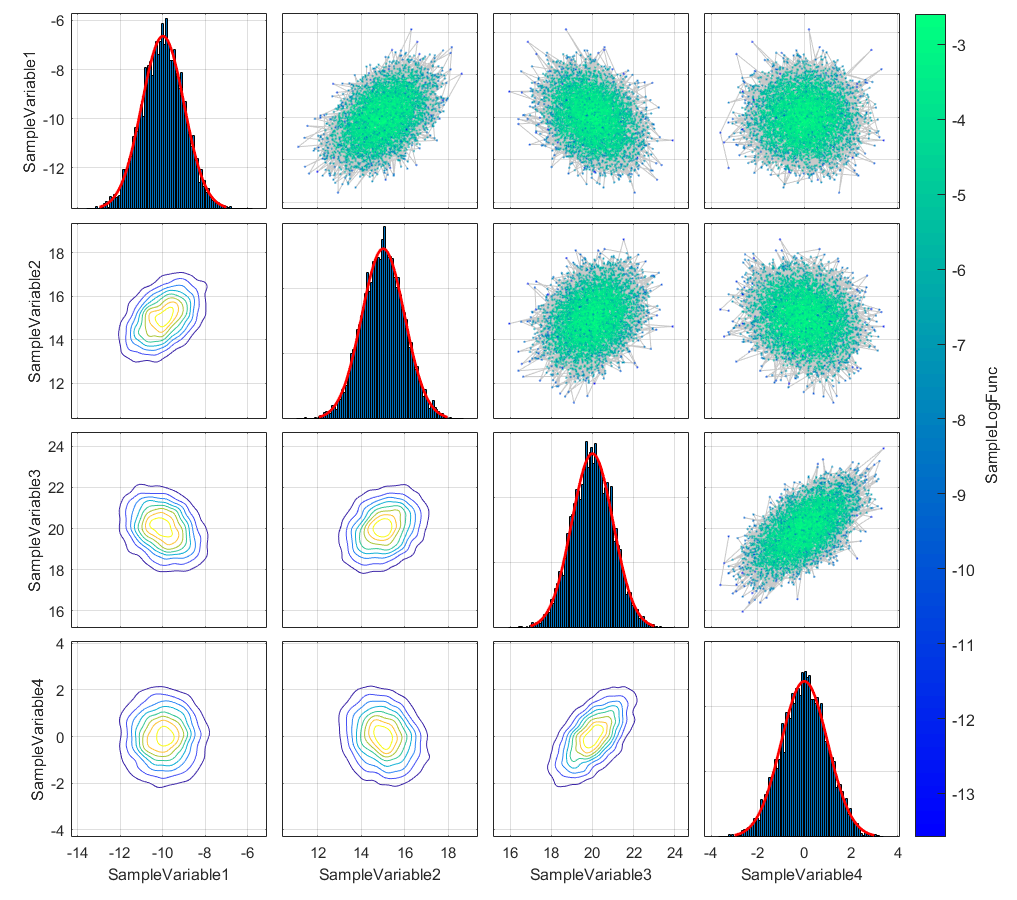

generating subplot #1: (1,1) out of 16
generating subplot #2: (1,2) out of 16
generating subplot #3: (1,3) out of 16
generating subplot #4: (1,4) out of 16
generating subplot #5: (2,1) out of 16
generating subplot #6: (2,2) out of 16
generating subplot #7: (2,3) out of 16
generating subplot #8: (2,4) out of 16
generating subplot #9: (3,1) out of 16
generating subplot #10: (3,2) out of 16
generating subplot #11: (3,3) out of 16
generating subplot #12: (3,4) out of 16
generating subplot #13: (4,1) out of 16
generating subplot #14: (4,2) out of 16
generating subplot #15: (4,3) out of 16
generating subplot #16: (4,4) out of 16


pmpd.sampleList{1}.plot.grid.layout.plotType.diag = "histfit"; % by default, MATLAB's histfit(), fits a Gaussian to the histogram data.
pmpd.sampleList{1}.plot.grid.plot("columns",[2,3,4,5]); % ignore the first column: SampleLogFunc as it is not Gaussian

We can also add **targets** to the subplots of the gridplot via **addTarget()**** method of the grid object,

pmpd.sampleList{1}.plot.reset("grid") % reset the plot settings to the original conditions

ParaDRAM - NOTE: resetting the properties of the grid plot...


pmpd.sampleList{1}.plot.grid.plot("columns",1:5);

generating subplot #1: (1,1) out of 25
generating subplot #2: (1,2) out of 25
generating subplot #3: (1,3) out of 25
generating subplot #4: (1,4) out of 25
generating subplot #5: (1,5) out of 25
generating subplot #6: (2,1) out of 25
generating subplot #7: (2,2) out of 25
generating subplot #8: (2,3) out of 25
generating subplot #9: (2,4) out of 25
generating subplot #10: (2,5) out of 25
generating subplot #11: (3,1) out of 25
generating subplot #12: (3,2) out of 25
generating subplot #13: (3,3) out of 25
generating subplot #14: (3,4) out of 25
generating subplot #15: (3,5) out of 25
generating subplot #16: (4,1) out of 25
generating subplot #17: (4,2) out of 25
generating subplot #18: (4,3) out of 25
generating subplot #19: (4,4) out of 25
generating subplot #20: (4,5) out of 25
generating subplot #21: (5,1) out of 25
generating subplot #22: (5,2) out of 25
generating subplot #23: (5,3) out of 25
generating subplot #24: (5,4) out of 25
generating subplot #25: (5,5) out of 25


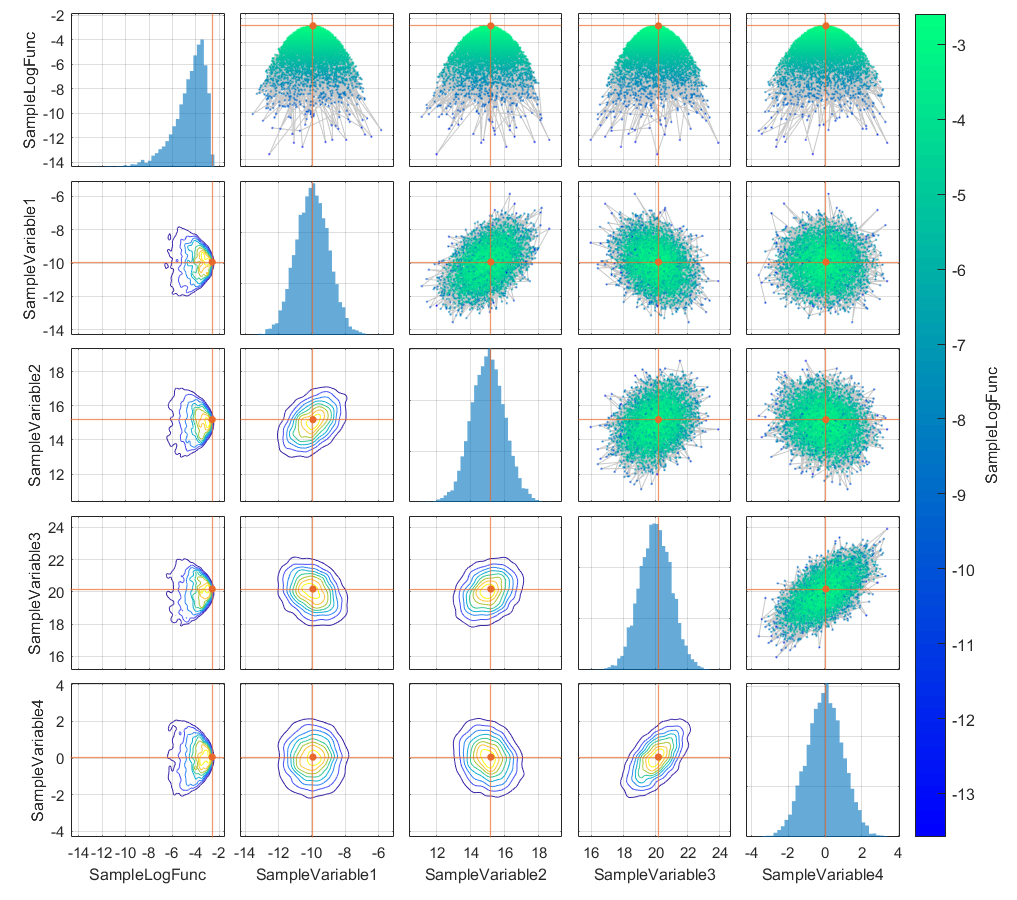

pmpd.sampleList{1}.plot.grid.addTarget() % no arguments will lead to adding the mode of SampleLogFunc as the targets to the plots

Instead of plotting the **mode** of SAmpleLogFunc, we can also plot other quantities of the variables, such as **mean** or **median** of the variables,

pmpd.sampleList{1}.plot.reset("grid") % reset the plot settings to the original conditions

ParaDRAM - NOTE: resetting the properties of the grid plot...


pmpd.sampleList{1}.plot.grid.plot("columns",1:5);

generating subplot #1: (1,1) out of 25
generating subplot #2: (1,2) out of 25
generating subplot #3: (1,3) out of 25
generating subplot #4: (1,4) out of 25
generating subplot #5: (1,5) out of 25
generating subplot #6: (2,1) out of 25
generating subplot #7: (2,2) out of 25
generating subplot #8: (2,3) out of 25
generating subplot #9: (2,4) out of 25
generating subplot #10: (2,5) out of 25
generating subplot #11: (3,1) out of 25
generating subplot #12: (3,2) out of 25
generating subplot #13: (3,3) out of 25
generating subplot #14: (3,4) out of 25
generating subplot #15: (3,5) out of 25
generating subplot #16: (4,1) out of 25
generating subplot #17: (4,2) out of 25
generating subplot #18: (4,3) out of 25
generating subplot #19: (4,4) out of 25
generating subplot #20: (4,5) out of 25
generating subplot #21: (5,1) out of 25
generating subplot #22: (5,2) out of 25
generating subplot #23: (5,3) out of 25
generating subplot #24: (5,4) out of 25
generating subplot #25: (5,5) out of 25


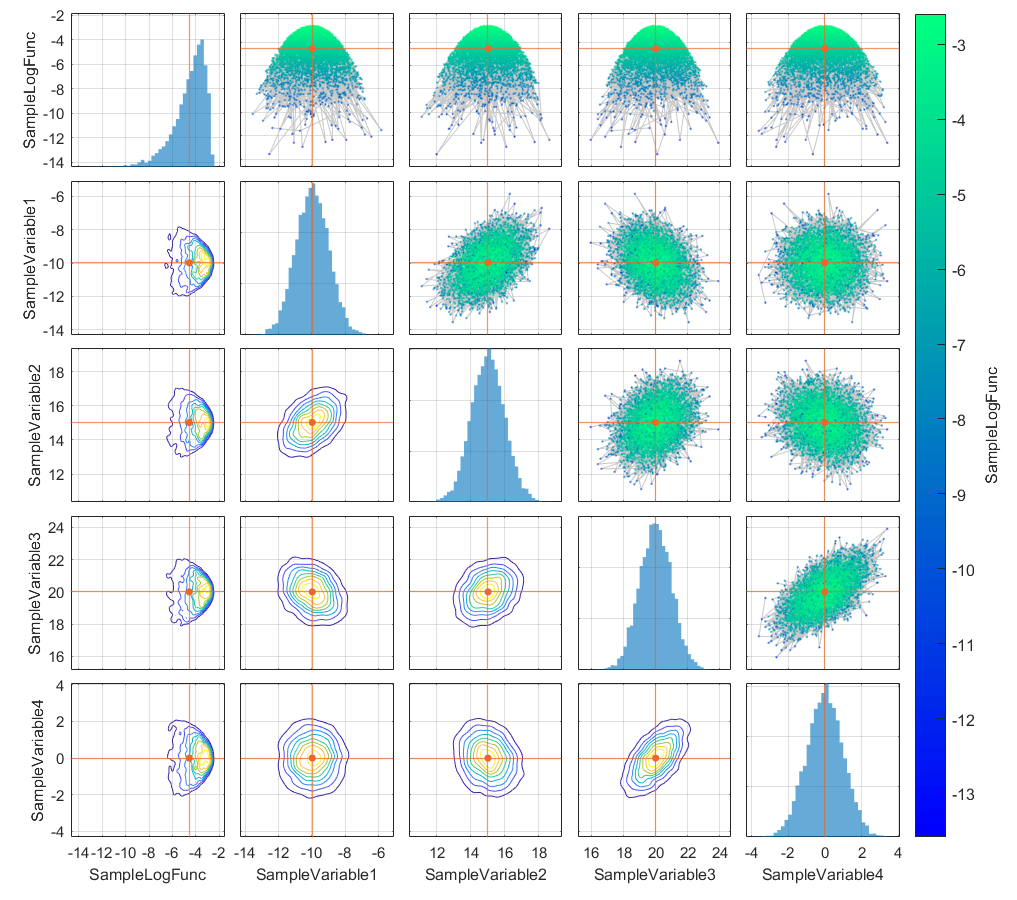

pmpd.sampleList{1}.plot.grid.addTarget("mean") % target will represent the means of the variables on each subplot

Now, let's say that we also want another set of target values to co-appear on these plots, for example, the last point that we have in our sample. We can also give the second group a different color, like the following, and in doing so, let's also hide the upper triangle of subplots,

pmpd.sampleList{1}.plot.reset("grid") % reset the plot settings to the original conditions

ParaDRAM - NOTE: resetting the properties of the grid plot...


pmpd.sampleList{1}.plot.grid.plot("columns",1:3);

generating subplot #1: (1,1) out of 9
generating subplot #2: (1,2) out of 9
generating subplot #3: (1,3) out of 9
generating subplot #4: (2,1) out of 9
generating subplot #5: (2,2) out of 9
generating subplot #6: (2,3) out of 9
generating subplot #7: (3,1) out of 9
generating subplot #8: (3,2) out of 9
generating subplot #9: (3,3) out of 9


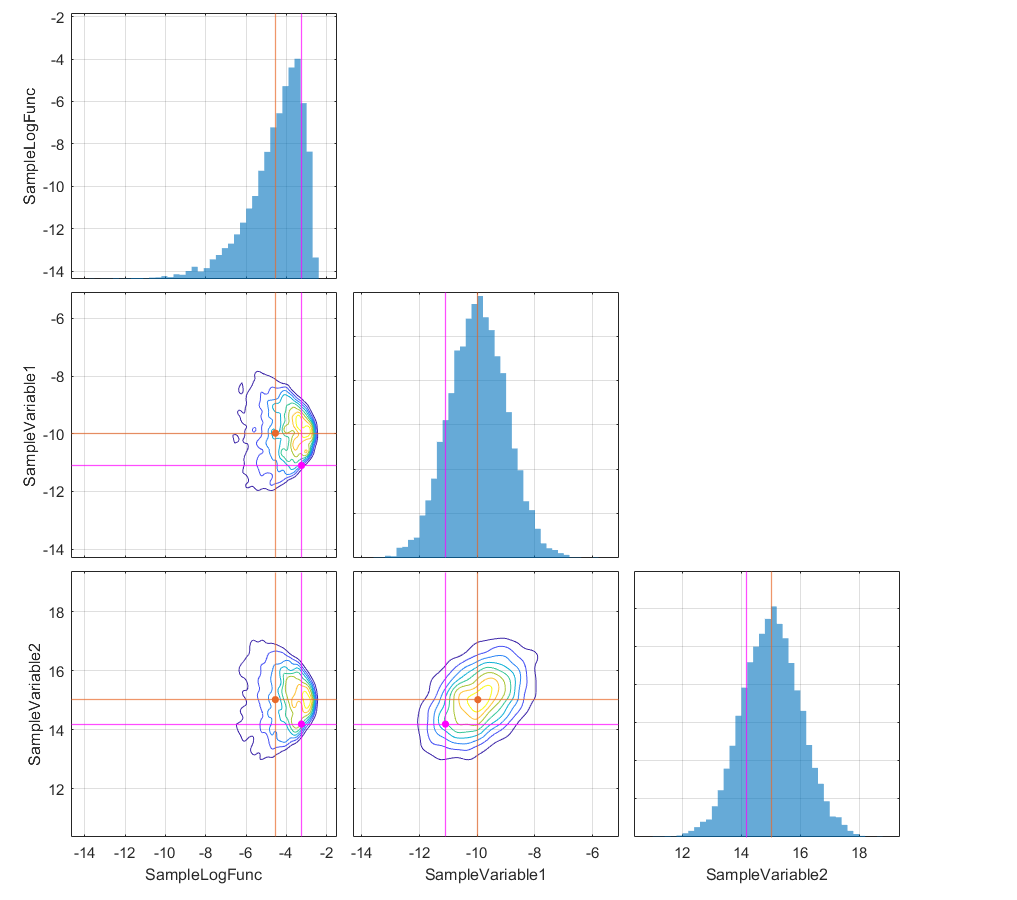

pmpd.sampleList{1}.plot.grid.addTarget("mean") % target will represent the means of the variables on each subplot
pmpd.sampleList{1}.plot.grid.addTarget  ( "values", pmpd.sampleList{1}.df{end,:} ...
                                        ,  "hline_kws", {'color','magenta'} ... the color of the horizontal lines
                                        ,  "vline_kws", {'color','magenta'} ... the color of the vertical lines
                                        ,  "scatter_kws", {'color','magenta'} ... the color of the target dot at the center
                                        ) % add the last sample as the extra target, with all colors set to magenta
pmpd.sampleList{1}.plot.grid.hide("upper","colorbar") % hides the upper traingle and colorbar. Undo it by pmpd.sampleList{1}.plot.grid.show("upper","colorbar").

**There are many more capabilities of the grid plot that were not discussed here, but you can always get help via (uncomment the following lines for help)**,

% pmpd.sampleList{1}.plot.grid.helpme("all")
% pmpd.sampleList{1}.plot.grid.helpme("plot")
% pmpd.sampleList{1}.plot.grid.helpme("addTarget")

There are many other types of plots that can be made. Let's make those plots with the Markov Chain instead.

pmpd.readMarkovChain()

ParaDRAM - WARNING: The ParaDRAM input simulation specification pmpd.spec.outputDelimiter is not set.
ParaDRAM - WARNING: This information is essential for successful reading of the requested chain file(s).
ParaDRAM - WARNING: Proceeding with the default assumption of comma-delimited chain file contents...
ParaDRAM - NOTE: 1 files detected matching the pattern: "./sampling_multivariate_normal_density_function_via_paradram/mvn_serial*"

ParaDRAM - NOTE: processing file: D:\Dropbox\Projects\20180101_ParaMonte\paramontex\MATLAB\mlx\sampling_multivariate_normal_density_function_via_paradram\mvn_serial_process_1_chain.txt
ParaDRAM - NOTE: reading file contents... 
ParaDRAM - NOTE: done in 0.624060 seconds.
ParaDRAM - NOTE: computing the sample correlation matrix...
ParaDRAM - NOTE: creating the heatmap plot object from scratch...
ParaDRAM - NOTE: done in 0.150020 seconds.
ParaDRAM - NOTE: computing the sample covariance matrix...
ParaDRAM - NOTE: creating the heatmap plot object from scratc

### DIGRESSION**: Ensuring diminishing adaptation in the adaptive MCMC sampling**

**================================================================================**

By default, the ParaDRAM sampler adapts the proposal distribution of the sampler throughout the entire simulation. This breaks the ergodicity condition of the Markov chain, however, if the adaptation tends to continuously and progressively diminish throughout the entire simulation, then we potentially trust the results. The alternative is to simply turn off the adaptation, but that is rarely a good strategy. Instead, **a better solution is to keep the adaptivity on, however, simulate for very long times to ensure convergence of the Markov chain to the target density**.

**A unique feature of the ParaDRAM sampler** is that, it provides a measure of the amount of adaptation of the proposal distribution of in the Markov chain by measuring how much the proposal distribution progressively changes throughout the simulation. In essence, the computed quantity, represented by the column **AdaptationMeasure** in the output chain file, represents an upper limit on the **total variation distance** of each updated proposal distribution with the last used proposal distribution before the update. We can plot the **AdaptationMeasure** for this sampling problem to ensure that the adaptation of the proposal distribution happens progressively less and less throughout the simulation. **If AdaptationMeasure does not diminish monotonically throughout the simulation, it is a strong indication of the lack of convergence of the MCMC sampler to the target objective function**.

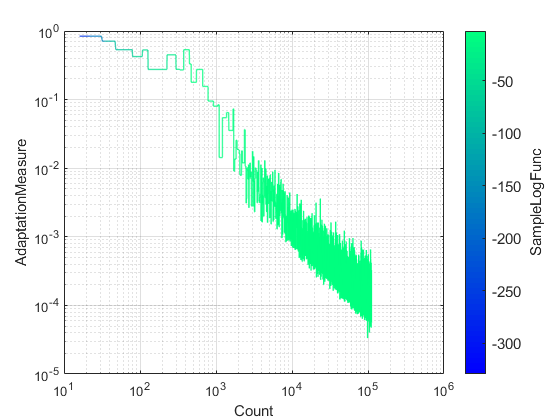

% first remove the zero values in Adaptation Measure for better
% illustration on log-log plot. set them all to nan, then convert nans to the last non-zero value in sequence.
pmpd.markovChainList{1}.plot.line.dfref.AdaptationMeasure(pmpd.markovChainList{1}.plot.line.dfref.AdaptationMeasure==0) = nan;
pmpd.markovChainList{1}.plot.line.dfref.AdaptationMeasure = fillmissing(pmpd.markovChainList{1}.plot.line.dfref.AdaptationMeasure,'previous');
pmpd.markovChainList{1}.plot.line.plot("ycolumns","AdaptationMeasure","colormap","winter")
set(gca,'xscale','log','yscale','log')

pmpd.markovChainList{1}.plot.reset("line") % reset the line plot to the original settings

ParaDRAM - NOTE: resetting the properties of the line plot...


**The above curve is exactly the kind of diminishing adaptation that we would want to see in a ParaDRAM simulation**: At the beginning, the sampler appears to struggle for a while to find the shape of the target objective function, but around step 1000, it appears to have found the peak of the target and starts to quickly converge to and adapt the shape of the proposal distribution of the Markov Chain sampler to the shape of the objective function.

Let's make a quick line trace plot of all variables in a single plot. But first, we have to keep in mind that the chain file contains more information than only the sampled points,

pmpd.markovChainList{1}.df.Properties.VariableNames

ans = 1×11 cell array
    {'ProcessID'}    {'DelayedRejectionStage'}    {'MeanAcceptanceRate'}    {'AdaptationMeasure'}    {'BurninLocation'}    {'SampleWeight'}    {'SampleLogFunc'}    {'SampleVariable1'}    {'SampleVariable2'}    {'SampleVariable3'}    {'SampleVariable4'}

We will only plot the sample columns,

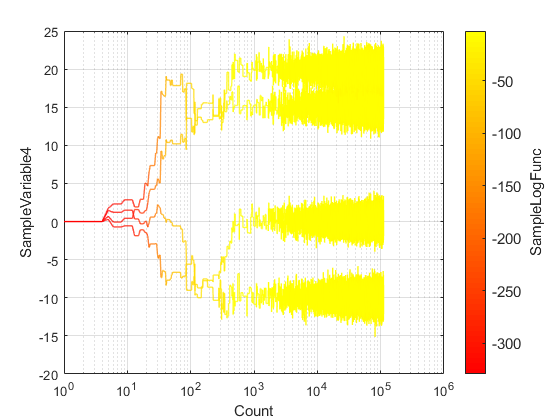

for varName = pmpd.markovChainList{1}.df.Properties.VariableNames(8:end) % only plot
    pmpd.markovChainList{1}.plot.line.plot("ycolumns",varName)
    pmpd.markovChainList{1}.plot.line.gcf_kws.enabled = false; % do NOT create new figure for each variable. This has the effects of "hold on" in MATLAB.
end
set(gca,'xscale','log','yscale','linear')

Let's turn off the varying-color. The varying-color is created via MATLAB's **surface()** function. We will therefore, disable this function and enabled the other plot-type, which is MATLAB's builtin **plot()** function, like the following,

pmpd.markovChainList{1}.plot.reset("line") % reset the plot settings to the default

ParaDRAM - NOTE: resetting the properties of the line plot...


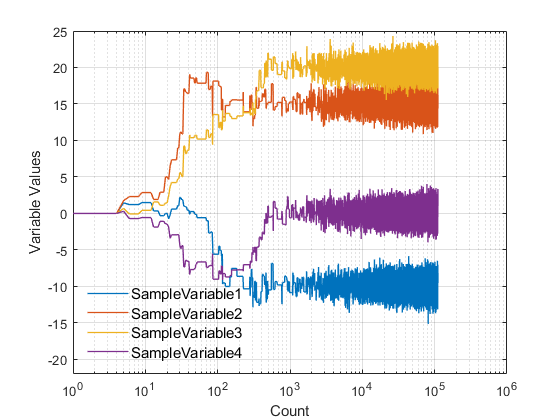

pmpd.markovChainList{1}.plot.line.surface_kws.enabled = false;
pmpd.markovChainList{1}.plot.line.plot_kws.enabled = true;
pmpd.markovChainList{1}.plot.line.plot( "ycolumns" , pmpd.markovChainList{1}.df.Properties.VariableNames(8:end), "legend_kws", {"location","southwest"} )
ylim( [ pmpd.markovChainList{1}.plot.line.currentFig.gca.YLim(1)-2 pmpd.markovChainList{1}.plot.line.currentFig.gca.YLim(2) ] ) ;
set(gca,'xscale','log','yscale','linear');

Let's make a 3D lineScatter plot,

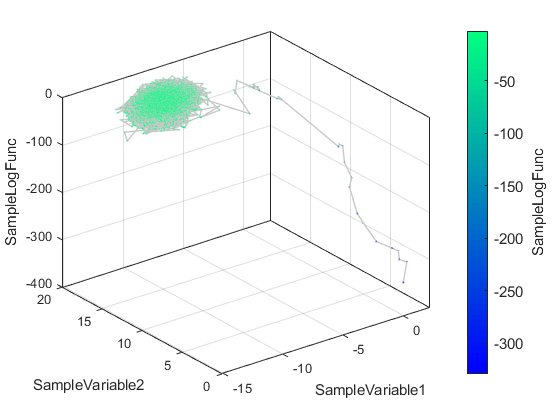

pmpd.markovChainList{1}.plot.lineScatter3.plot()

Because of the bad initial starting point of the sampling (which was intentional in this example), the colormap does not show the colors well close to the peak of the objective function. One solution is to cut the initial part of the sample that is causing the color-problem,

pmpd.markovChainList{1}.count % the total number of sampled points

ans =       111085

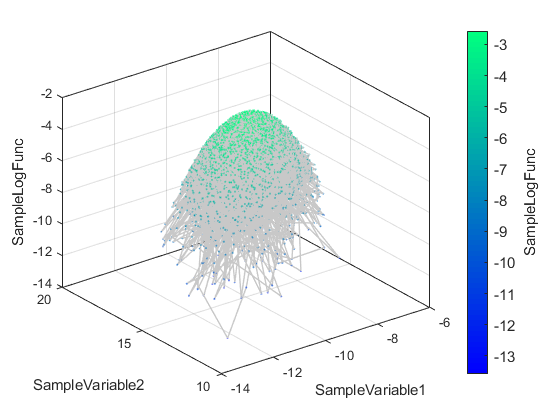

pmpd.markovChainList{1}.plot.lineScatter3.plot("rows", 1000:10:pmpd.markovChainList{1}.count ) % we will skip the first 10 points, and will include every other point (for the purpose of illustration).

Note that in the above and in all other cases in this example, you can always set the properties in two ways, either passing them as keyword arguments to the **plot()** function, or directly setting them as object properties. For example,

pmpd.markovChainList{1}.plot.lineScatter3.rows = 1000:10:pmpd.markovChainList{1}.count;

We can also make contour plots of bivariate density-maps of data. But let's make these plots for the set of uniquely-sampled points in the chain file (that is, the Markov chain in compact format),

pmpd.readChain();

ParaDRAM - WARNING: The ParaDRAM input simulation specification pmpd.spec.outputDelimiter is not set.
ParaDRAM - WARNING: This information is essential for successful reading of the requested chain file(s).
ParaDRAM - WARNING: Proceeding with the default assumption of comma-delimited chain file contents...
ParaDRAM - NOTE: 1 files detected matching the pattern: "./sampling_multivariate_normal_density_function_via_paradram/mvn_serial*"

ParaDRAM - NOTE: processing file: D:\Dropbox\Projects\20180101_ParaMonte\paramontex\MATLAB\mlx\sampling_multivariate_normal_density_function_via_paradram\mvn_serial_process_1_chain.txt
ParaDRAM - NOTE: reading file contents... 
ParaDRAM - NOTE: done in 0.868540 seconds.
ParaDRAM - NOTE: computing the sample correlation matrix...
ParaDRAM - NOTE: creating the heatmap plot object from scratch...
ParaDRAM - NOTE: done in 0.267030 seconds.
ParaDRAM - NOTE: computing the sample covariance matrix...
ParaDRAM - NOTE: creating the heatmap plot object from scratc

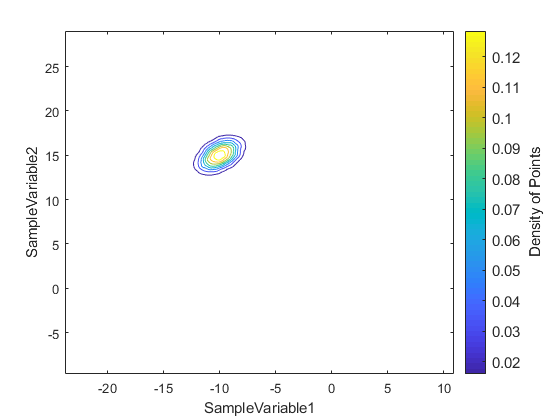

pmpd.chainList{1}.plot.contour.plot()

Again, removing the initial burnin points from the compact chain will lead to a much more resolved figure,

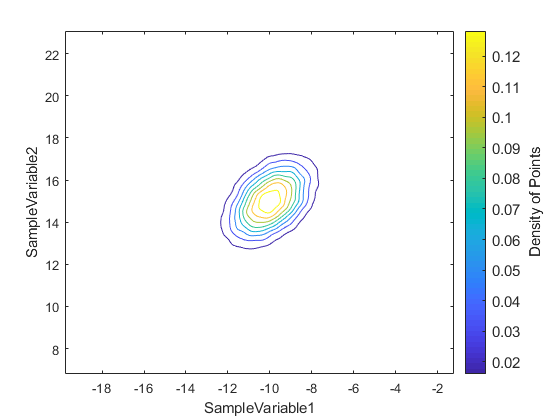

pmpd.chainList{1}.plot.contour.plot("rows",100:pmpd.chainList{1}.count)

We can also make filled contour plots of the bivariate density-maps of data,

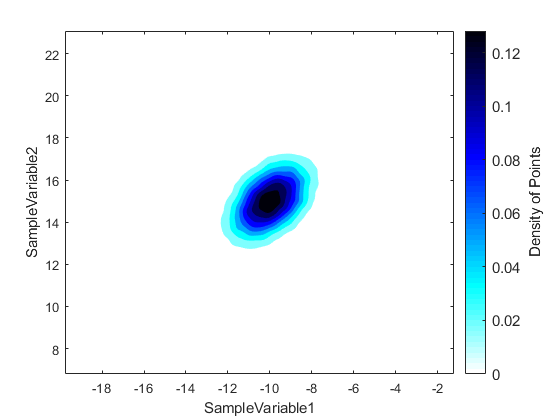

pmpd.chainList{1}.plot.contourf.plot("rows",100:pmpd.chainList{1}.count)

or, make 3D contour plots of the density of the bivariate density-maps of data,

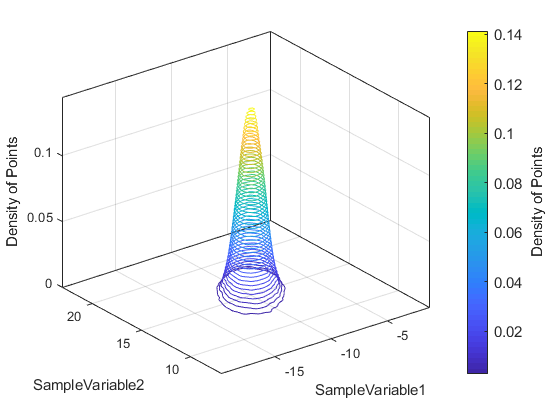

pmpd.chainList{1}.plot.contour3.plot("rows",100:pmpd.chainList{1}.count)

## Inspecting the autocorrelation of the MCMC chain and the final sample

**====================================================================================**

By default, the ParaDRAM sampler will **decorrelate** and **refine** the MCMC chain to the highest levels possible until it cannot detect any residual autocorrelation in the refined sample. Now, let's first take a look at the the autocorrelation plots of the raw MCMC chain, 

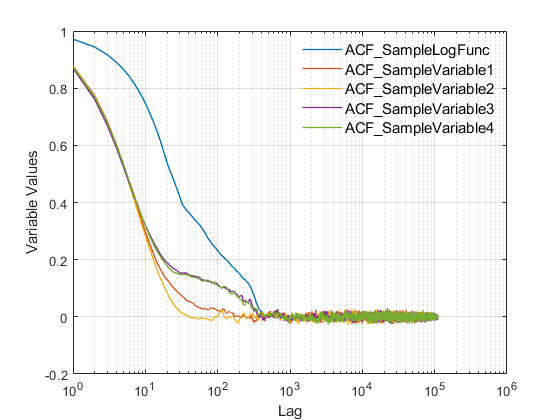

pmpd.markovChainList{1}.stats.autocorr.plot.line.plot()
set(gca,'xscale','log','yscale','linear');

For comparison, here is the autocorrelation plot of the variables of the final refined decorrelated sample,

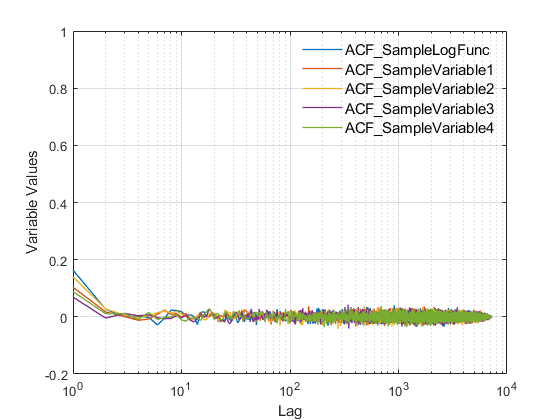

pmpd.sampleList{1}.stats.autocorr.plot.line.plot()
% For better comparison, we will set the Y-axis limits of the two plots to the same range in the following line.
pmpd.sampleList{1}.stats.autocorr.plot.line.currentFig.gca.YLim = pmpd.markovChainList{1}.stats.autocorr.plot.line.currentFig.gca.YLim;
set(gca,'xscale','log','yscale','linear');

The above AutoCorrelation plot for the refined sample is reassuring since the sampled points do not appear to be correlated with each other at all. This is because the ParaDRAM routine, by default, applies as many rounds of refinements and decorrelating of the Markov chain as necessary to remove any residual correlations from the final output random sample.

By contrast, unlike the refined sample, the Markov chain is significantly correlated  with itself along each dimension. The large amount of autocorrelation  seen for `SampleLogFunc` is because of the fact that we  started the MCMC sampling from a very bad low-probability location,  which is also visible the grid plots in the above.

To construct and visualize the correlation matrix of the sampled points in the chain, try,

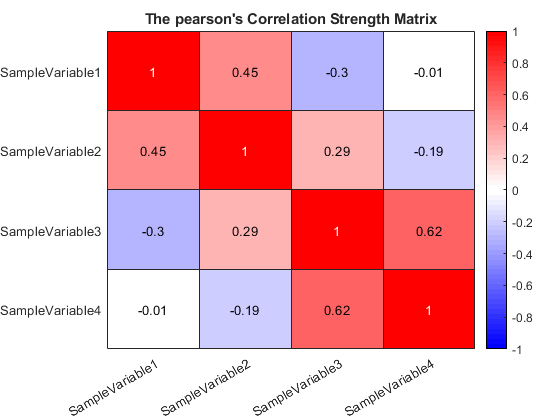

pmpd.sampleList{1}.stats.cormat.plot.heatmap.plot()

`For comparison, here is `the correlation matrix of the raw Markov chain, 

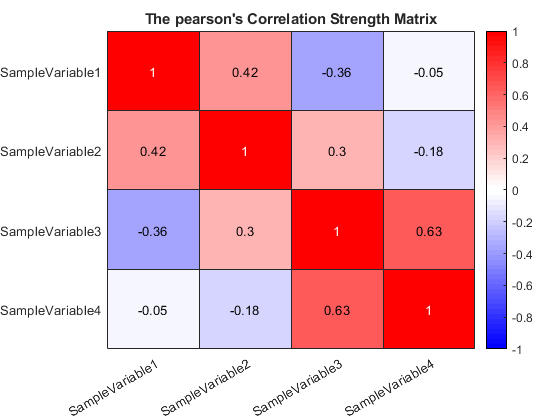

pmpd.markovChainList{1}.stats.cormat.plot.heatmap.plot()

The two plots are mostly consistent with each other, an indication that  good convergence has occurred, and that the requested chainSize of 30000 unique points was more than enough to obtain a reasonable number i.i.d. random samples from the objective function.

You can also visualize the covariance matrix of the sample,

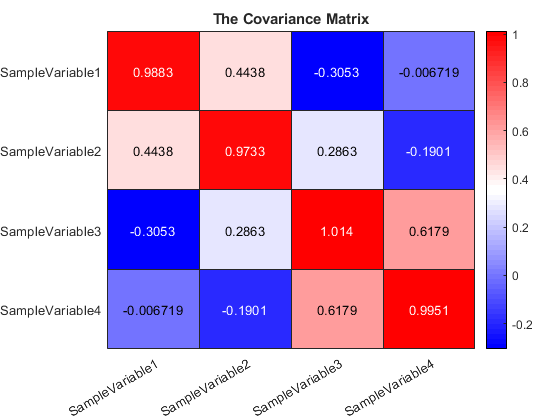

pmpd.sampleList{1}.stats.covmat.plot.heatmap.plot()

`For comparison, here is `the correlation matrix of the raw Markov chain, 

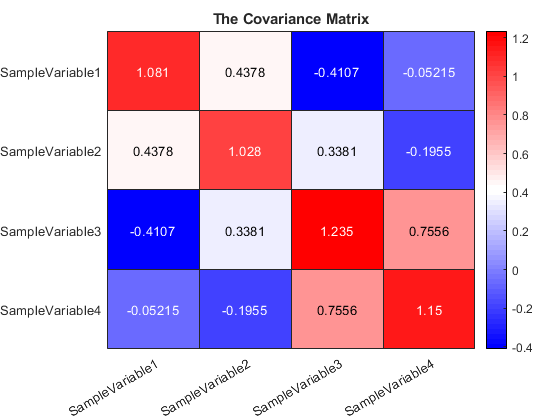

pmpd.markovChainList{1}.stats.covmat.plot.heatmap.plot()

## Running a single-chain ParaDRAM simulation in parallel on multiple processors

**===============================================================================================**

For large scale time-intensive problems, you can also run the ParaDRAM sampler in parallel on multiple processors, and with as many processors as needed. One unique feature of the parallelization capabilities of the ParaMonte library is that, you do not need to code anything in your objective function in parallel. You do not even need to have the MATLAB parallel Toolbox installed on your system. All parallelizations and communications is automatically handled by the ParaMonte library routines. For instructions on how to sample your expensive objective functions in parallel, visit [the ParaMonte library's documentation website](https://www.cdslab.org/paramonte/notes/run/matlab/). 

## Final Remarks

**=================**

**There are many more functionalities and features of the  ParaMonte library that were neither explored nor mentioned in this  example Jupyter notebook. You can explore them by checking the existing  components of each attribute of the ParaDRAM sampler class and by  visiting the **[**ParaMonte library's documentation website**](http://cdslab.org/paramonte/).